# Dataset Information

The dataset was downloded from "https://archive.ics.uci.edu/dataset/235/individual+household+electric+power+consumption" and contains power consumption data of one home located in located in Sceaux (7km of Paris, France) between December 2006 and November 2010 (47 months). The variables included in the data set are as follows.

1.date: date in format dd/mm/yyyy 

2.time: time in format hh:mm:ss 

3.global_active_power: household global minute-averaged active power (in kilowatt) 

4.global_reactive_power: household global minute-averaged reactive power (in kilowatt) 

5.voltage: minute-averaged voltage (in volt) 

6.global_intensity: household global minute-averaged current intensity (in ampere) 

7.sub_metering_1: energy sub-metering No. 1 (in watt-hour of active energy). It corresponds to the kitchen, containing mainly a dishwasher, an oven and a microwave (hot plates are not electric but gas powered). 

8.sub_metering_2: energy sub-metering No. 2 (in watt-hour of active energy). It corresponds to the laundry room, containing a washing-machine, a tumble-drier, a refrigerator and a light. 

9.sub_metering_3: energy sub-metering No. 3 (in watt-hour of active energy). It corresponds to an electric water-heater and an air-conditioner.

***Note:-The values in the sub_metering_* variables when combined togather do not represent the consumption in the entire house.***

# Data Preprocessing

#### Time Format Correction

The time information in the dataset is represented by two columns: Date and Time. In order to make plotting data against time easier, in this section the columns "Date" and "Time" are being merged into a column named "DateTime", which is in MATLAB's datetime format. 

Date_time = datetime(year(householdpowerconsumption.Date),month(householdpowerconsumption.Date),day(householdpowerconsumption.Date),hour(householdpowerconsumption.Time),minute(householdpowerconsumption.Time),second(householdpowerconsumption.Time));
Master_Data = addvars(householdpowerconsumption,Date_time,'NewVariableNames',"DateTime", 'Before',"Date");
Master_Data = removevars(Master_Data,["Date" "Time"]);

#### Handling Missing Values and Normalizing

No_of_Missing_Values_per_Variable = sum(ismissing(Master_Data))

No_of_Missing_Values_per_Variable =            0       25979       25979       25979       25979       25979       25979       25979


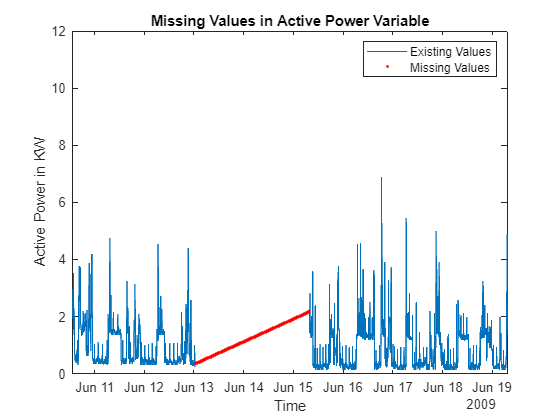

plot(Master_Data.DateTime,Master_Data.Global_active_power)
hold on
Missing_index = ismissing(Master_Data.Global_active_power);
Data_with_filled_entries = fillmissing(Master_Data,"linear", "DataVariables","Global_active_power");
Filled_entries = Data_with_filled_entries(Missing_index,:);
scatter(Filled_entries.DateTime, Filled_entries.Global_active_power,"red",".")
hold off
xlabel("Time")
ylabel("Active Power in KW")
title("Missing Values in Active Power Variable")
legend(["Existing Values", "Missing Values"])
xlim([datetime(2009,6,10,13,30,10) datetime(2009,6,19,7,10,56)])
ylim([0.0 12.0])

As can be seen in the output above the dataset has almost 26000 missing values. Looking at the plotted example, in some sections continuous values are missing. Efforts of filling such continuous sections will not be very effective as noticeable in the above plot. As we are planning to detect anomalies and are not doing any forecasting in the following sections, it is better to remove the missing values then to fill them by prediction. This will save the calculation from being impacted by values that were added by predictions. Normalization using Z-score is also being performed on data that will be used by the K-means function. This is being done to avoid variables with larger values disproportionately influencing the calculations.  

Cleaned_Data = rmmissing(Master_Data);
Noramlized_and_Cleaned_Data = normalize(Cleaned_Data, "DataVariables",["Global_active_power","Global_reactive_power","Voltage","Global_intensity","Sub_metering_1","Sub_metering_2","Sub_metering_3"]);

# Exploratory Data Analysis (EDA)

#### Exploration of the Whole Dataset

Creating the 3D histogram reveals the distribution of the active power in relation to the voltage. Voltage has been selected for processing here as we know that power consumption impacts voltage, as the resistance increases due to increased power flow. The histogram reveals that virtually all of the values are clustered in a single collection.

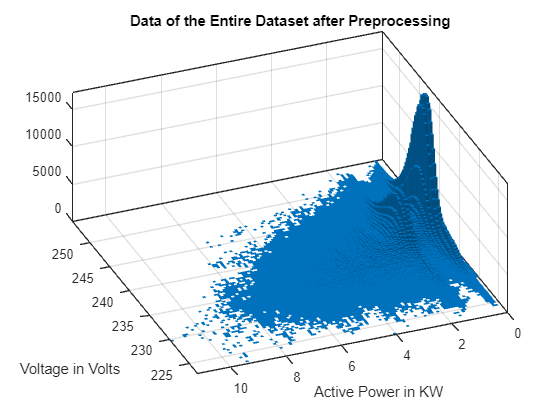

histogram2(Cleaned_Data.Voltage, Cleaned_Data.Global_active_power, "DisplayName","Global_active_power");
xlabel("Voltage in Volts")
ylabel("Active Power in KW")
title("Data of the Entire Dataset after Preprocessing")
view([-112 52])

#### Exploration of the Selected portion of the Dataset

We know that the dataset contains more than 2 million entries for a period of around 4.5 years. Analyzing such a large amount of data is computationally intensive. Such analysis is also not very effective due to the variability of the data. As a result it has been decided to select entries corresponding to a particular weekday in a month for anomaly detection using K-means clustering algorithm.  

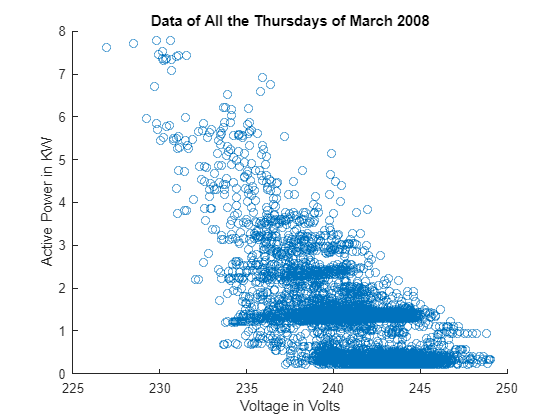

Data = Cleaned_Data;
Noramlized_Data = Noramlized_and_Cleaned_Data;
Selected_Year = 2008;
Selected_Month = 3;
% Selected_Day = 18; % Rather than selecting WeekDay a particular Date can be selected 
Selected_Weekday = 5;
Selected_entries = year(Data.DateTime)==Selected_Year & month(Data.DateTime)==Selected_Month & weekday(Data.DateTime)==Selected_Weekday; %& day(Data.DateTime)==Selected_Day; 
Data = Data(Selected_entries,:);
Noramlized_Data = Noramlized_Data(Selected_entries,:);
Month_name = cell2mat(month(Data.DateTime(1,:),'name'));
[~, Weekday_name] =weekday(Data.DateTime(1,:),'long');
Title_text = sprintf('Data of All the %ss of %s %d', Weekday_name, Month_name, Selected_Year);
X = Data.Voltage;
Y = Data.Global_active_power;
X_Normalized = Noramlized_Data.Voltage;
Y_Normalized = Noramlized_Data.Global_active_power;

scatter(X, Y)
xlabel("Voltage in Volts")
ylabel("Active Power in KW")
title(Title_text)

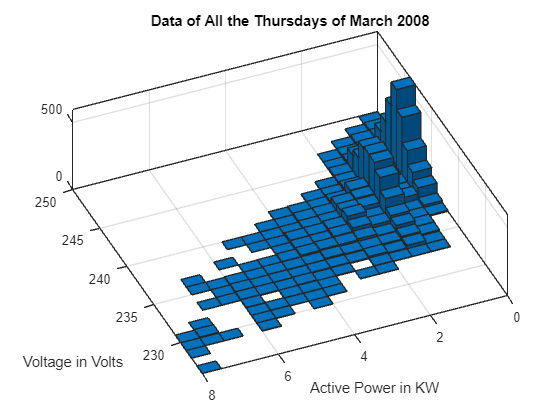

% Create histogram2 of selected data
histogram2(X, Y,"DisplayName","Global_active_power");
xlabel("Voltage in Volts")
ylabel("Active Power in KW")
title(Title_text)
view([-113 68])

# Anomaly Detection using K-means Clustering

The Task asked for anomaly detection in power consumption. As large deviations in power consumption were not present it has been decided to shift to anomaly detection in voltage while also taking into account the power consumption at that point in time.

#### Feature Selection

As mentioned, consumption can have a significant impact on voltage. The anomalies that we are planning to detect are issues in voltage values when considered with contemporary power consumption. As a result the 'Voltage" variable along with "Global_active_power" has been selected to be passed to the Kmeans function.  

#### **Selection of K - Number of Clusters**

The selection of the right number of clusters is essential for detecting the anomalies. We know the values are not making multiple clusters which are clearly set apart, but EDA has revealed that values are concentrated in some areas. If the values for a weekday in the selected month are more dispersed than increasing the number clusters will be beneficial, as the anomaly detection will be done at cluster level without getting impacted by large concentrations of points in other clusters that are at some distance from other points.    

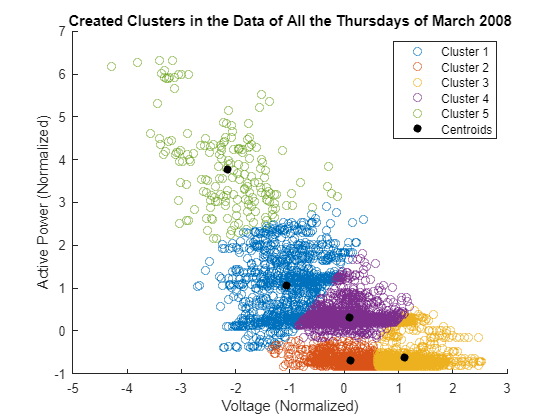

No_of_clusters = 5;
[groupNum,C] = kmeans([X_Normalized Y_Normalized],No_of_clusters);
legend_names = [];
figure
hold on
for i = 1:No_of_clusters
    scatter(X_Normalized(groupNum==i), Y_Normalized(groupNum==i))
    legend_names = [legend_names, sprintf("Cluster %d",i)];
end
scatter(C(:,1), C(:,2),'filled',"black")
xlabel("Voltage (Normalized)")
ylabel("Active Power (Normalized)")
title(sprintf("Created Clusters in the %s",Title_text))
legend([legend_names,"Centroids"])
hold off

#### Detecting Anomalies using Euclidean Distance Between Cluster Values

After the clusters have been formed, anomaly detection is to be done based on the total euclidean distance each point has with other points in the same cluster. A portion of points that is farthest from the other values in the cluster will be classified as anomalies. The size of this portion can be selected using the "Portion_of_Anomalies" variable. The portion size is the same for all the clusters, and is to be adjusted as the number of clusters are changed.

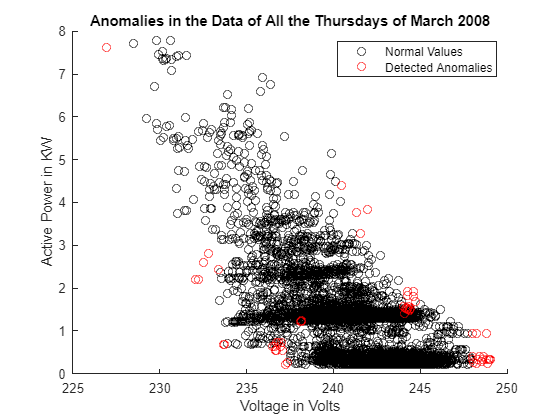

Portion_of_Anomalies = 0.01; % 0.1 means 10 anomalies in 100 values 
clf
plot_X = [];
plot_Y = [];
plot_anomalies_X = [];
plot_anomalies_Y = [];
for i = 1:No_of_clusters
    X_of_cluster = X(groupNum==i);
    Y_of_cluster = Y(groupNum==i);
    plot_X = [plot_X ; X_of_cluster];
    plot_Y = [plot_Y ; Y_of_cluster];
    distances = pdist([X_of_cluster, Y_of_cluster]);
    [~,I] = sort(sum(squareform(distances)));
    cluster_size = length(I);
    anomaly_index_of_cluster = I((end-floor(cluster_size*Portion_of_Anomalies)):end);
    plot_anomalies_X = [plot_anomalies_X ; X_of_cluster(anomaly_index_of_cluster)];
    plot_anomalies_Y = [plot_anomalies_Y ; Y_of_cluster(anomaly_index_of_cluster)];
end
scatter(plot_X, plot_Y, "black")
hold on
scatter(plot_anomalies_X, plot_anomalies_Y,"red")
legend("Normal Values","Detected Anomalies")
xlabel("Voltage in Volts")
ylabel("Active Power in KW")
title(sprintf("Anomalies in the %s",Title_text))
hold off

# Comments on Results

The anomalies being detected are combinations of voltage and active power that do not frequently occur on the selected weekday, as a result they fall on the border of the portion of the plot that contains the main concentration of points. If the ratio of the height and width of the dense part of the plotted data is very different from 1 then using more number of clusters is better as the anomaly detection will be localized in clusters spread over the larger dimension of the concentration.